close all; clear all

# **DYNAMICS AND CONTROL OF VEHICLES AND ROBOTS**

## Example: Lateral dynamics transfer functions estimation

**University of Trento**

*A.Y. 2019/2020*

F. Biral

E. Pagot

## Intro

In this script the telemetry data from the P1 experimental vehicles are loaded. This Matlab Live Script can be used as the structure for your project script.

Click "Save as..." and save this script as .m in order to obtain a classic Matlab script.

## Load Vehicle Parameters

The script loads the vehicle main parameters in the `vehicle` struct. See the script `p1_parameters.m` for comments about parameters names and units.

p1_parameters

## Load Datasets

The following test are available.

**DATASET NAME DESCRIPTION**

RAMP_STEER_L Left-hand ramp steer 10 m/s

RAMP_STEER_R Right-hand ramp steer 10 m/s

SINE_STEER_IS Sine wave steering at increasing speeds

SP_100FT_CR_IS_CCW Steering pad 100 ft circle constant radius increasing speed counter-clockwise

SP_100FT_CR_IS_CW Steering pad 100 ft circle constant radius increasing speed clockwise

STRAIGHT_LINE_0 Straight line at constant speed

STRAIGHT_LINE_1 Straight line in one direction

STRAIGHT_LINE_2 Straight line in the opposite direction

STEP_STEER Step steer

RANDOM_STEER Driving around with various steering rates

load("RANDOM_STEER.mat");
telem = RANDOM_STEER;

The loaded variable is a struct cointaing the following telemetry signals:

% DATA			UNITS		DESCRIPTION
% time                  s               acquisition time
% yaw			rad		yaw angle
% yaw_rate		rad/s 		yaw rate at COM
% roll			rad		roll at COM
% roll_rate		rad/s 		roll rate at COM
% long_vel		m/s 		longitudinal velocity of the COM
% lat_vel		m/s 		lateral velocity of the COM
% axG			m/s^2		longitudinal acceleration of the COM
% ayG			m/s^2 		lateral acceleration of the COM
% body_slip		rad		vehicle side slip angle (at COM)
% omega_FL		rad/s 		wheel angular speed
% omega_FR		rad/s 		wheel angular speed
% omega_RL		rad/s 		wheel angular speed
% omega_RR		rad/s 		wheel angular speed
% front_slip_angle      rad		equivalent (single track) slip angle at front axle
% rear_slip_angle       rad		equivalent (single track) slip angle at rear axle
% Fx_FL			N		tyre longitudinal force
% Fy_FL			N		tyre lateral force
% Fz_FL			N		tyre vertical force
% Fx_FR			N		tyre longitudinal force
% Fy_FR			N		tyre lateral force
% Fz_FR			N		tyre vertical force
% x_pos			m		COM position x coordinate (from GPS)
% y_pos			m		COM position y coordinate (from GPS)
% z_pos			m		COM position z coordinate or altitude (from GPS)
% delta_L		rad		steering angle of the front left wheel
% delta_R		rad		steering angle of the front right wheel
% delta_HW 		rad		handwheel steering angle

## Transfer function estimation 

Estimate the transfer functions between the steering angle $\delta$ and the side-slip angle $\beta$ and yaw rate $\Omega$. 


$$G_{\beta} = \frac{\beta(s)}{\delta(s)}$$
 


$$G_{\Omega} = \frac{\Omega(s)}{\delta(s)}$$


We would like to neglect the effect of the longitudinal dynamics, thus we choose the data where the longitudinal velocity is (almost) constant.

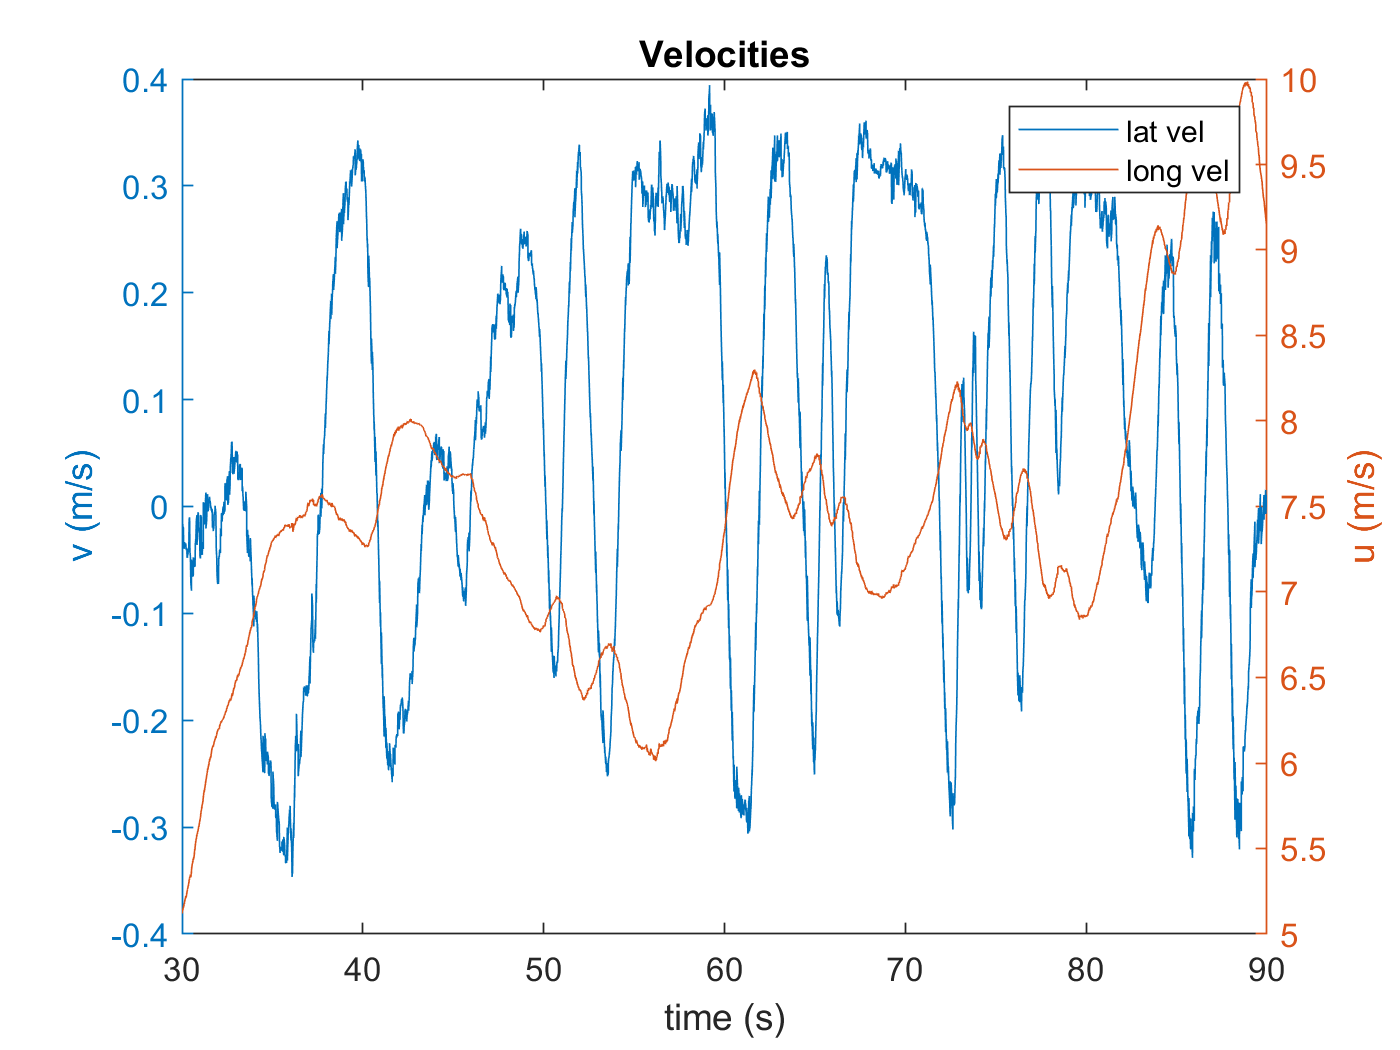

figure
yyaxis left
plot(telem.time,telem.lat_vel,'DisplayName','lat vel')
xlabel('time (s)');ylabel('v (m/s)');
title('Velocities');

yyaxis right
plot(telem.time,telem.long_vel,'DisplayName','long vel')
xlabel('time (s)');ylabel('u (m/s)');
legend

For instance, we can choose the data in the time period between 60 and 80 seconds.

idx_start = find(telem.time > 60);
idx_end = find(telem.time > 80);

## Analytical transfer functions 

Firstly, we compute the analytical transfer fucntions using the linearized Single-Track model. The MATLAB function `LinSingleTrackStateSpace` returns the matrices of the State-Space representation of the linear Single-Track model and it takes the vehicle parameters as input. The SS representation has the following structure:

States => [beta; Omega,Fyr,Fyf] 

Inputs => [delta] 

Outputs => [beta; Omega]

Here the parameters of the SS are defined. We take the mean value of the longitudinal speed in the selected time period as the constant velocity V. 


% C__f -> front axle cornering stiffness
P(1) = vehicle.C_a_f;

% C__r -> rear axle cornering stiffness
P(2) = vehicle.C_a_r;

% J -> yaw rotational inertia
P(3) = vehicle.Izz;

% V -> longitudinal speed 
P(4) = mean(telem.long_vel(idx_start:idx_end));

% l__f -> COM-Front Axle Distance
P(5) = vehicle.Lf;

% l__r -> COM-Rear Axle Distance
P(6) = vehicle.Lr;

% m -> vehicle mass
P(7) = vehicle.mass;

%lambda__f
P(8) = 0.4;

%lambda__r
P(9) = 0.4;


[A_matrix,B_matrix,C_matrix,D_matrix] = LinSingleTrackStateSpace_tyre_dyn(P);



Now that matrices A,B,C,D are computed, we can create a State-Space object using the MATLAB command `ss`.


SingleTrackSS = ss(A_matrix,B_matrix,C_matrix,D_matrix);


We can now compute and plot the four analytical transfer functions:

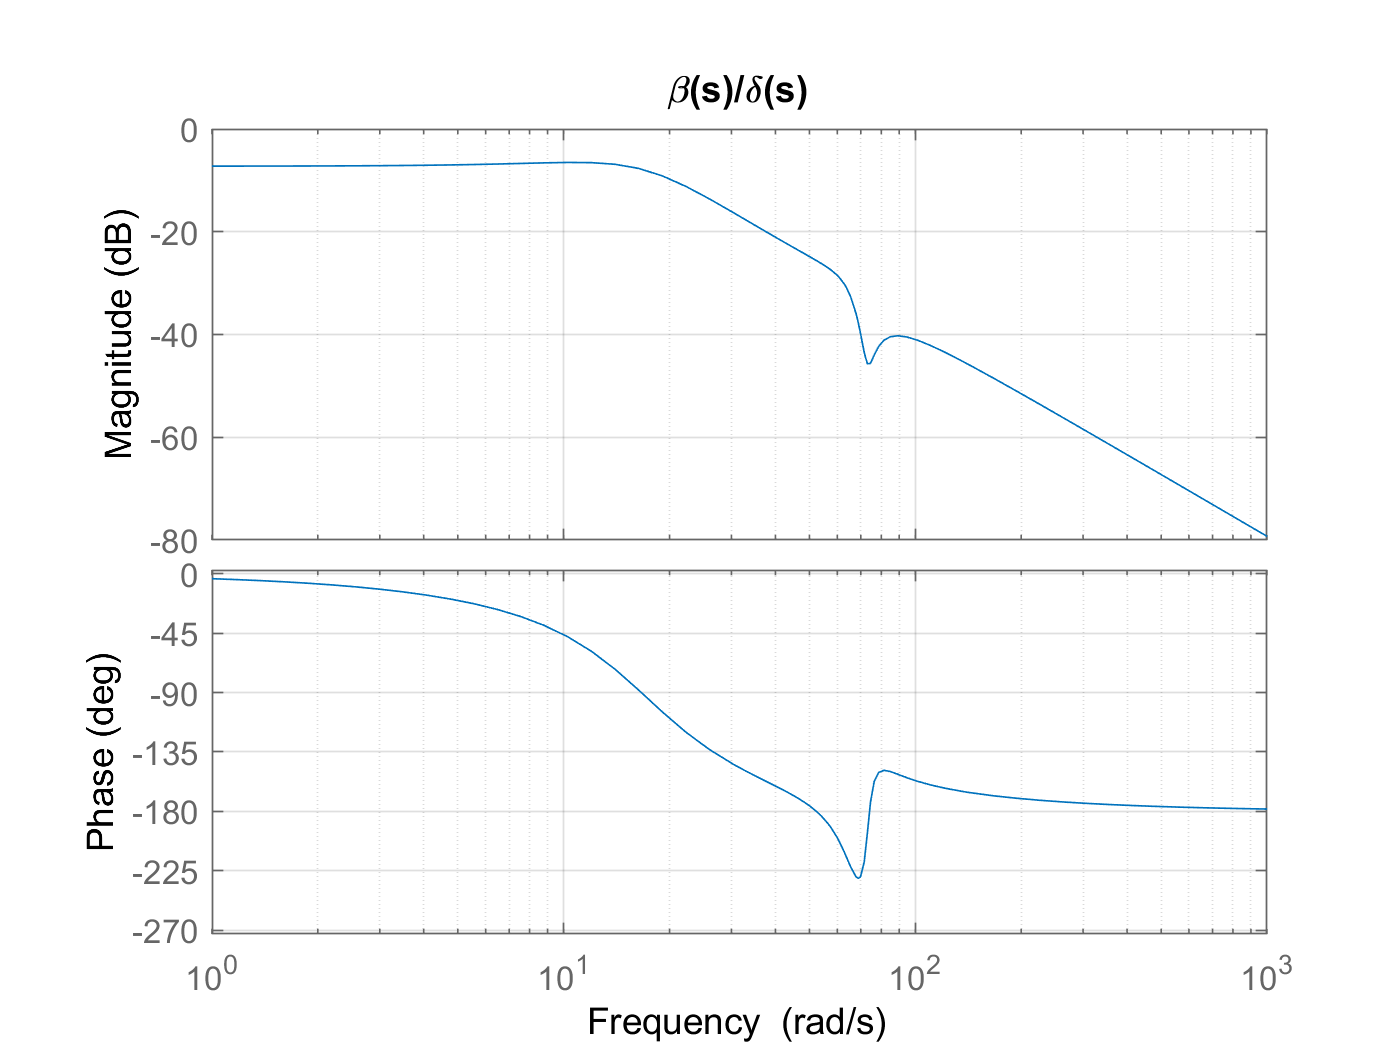

% Plot beta(s)/delta(s) transfer function

figure
bode(SingleTrackSS(1,1))
grid
title('\beta(s)/\delta(s)')


fprintf(' The analytical transfer function beta(s)/delta(s) is: \n');

 The analytical transfer function beta(s)/delta(s) is: 


G_beta = tf(SingleTrackSS(1,1))

G_beta =
 
            108.8 s^2 + 579.3 s + 5.818e05
  --------------------------------------------------
  s^4 + 37.52 s^3 + 5206 s^2 + 9.185e04 s + 1.339e06
 
Continuous-time transfer function.



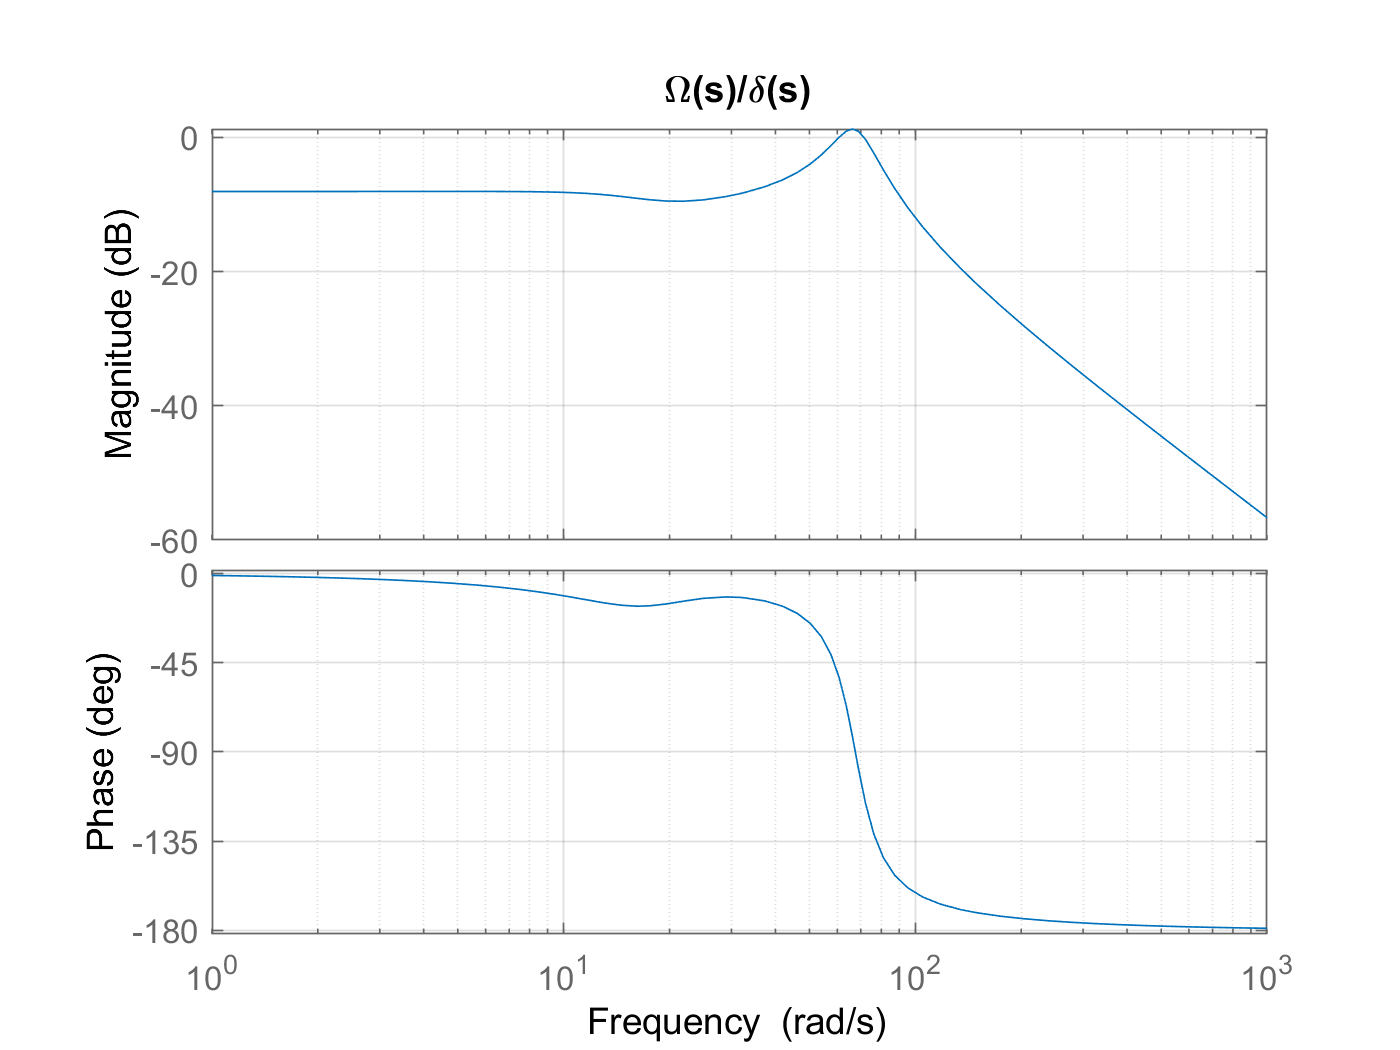

% Plot Omega(s)/delta(s) Transfer function

figure
bode(SingleTrackSS(2,1))
grid
title('\Omega(s)/\delta(s)')


fprintf(' The analytical transfer function Omega(s)/delta(s) is: \n');

 The analytical transfer function Omega(s)/delta(s) is: 


G_Omega = tf(SingleTrackSS(2,1))

G_Omega =
 
           1461 s^2 + 2.742e04 s + 5.298e05
  --------------------------------------------------
  s^4 + 37.52 s^3 + 5206 s^2 + 9.185e04 s + 1.339e06
 
Continuous-time transfer function.



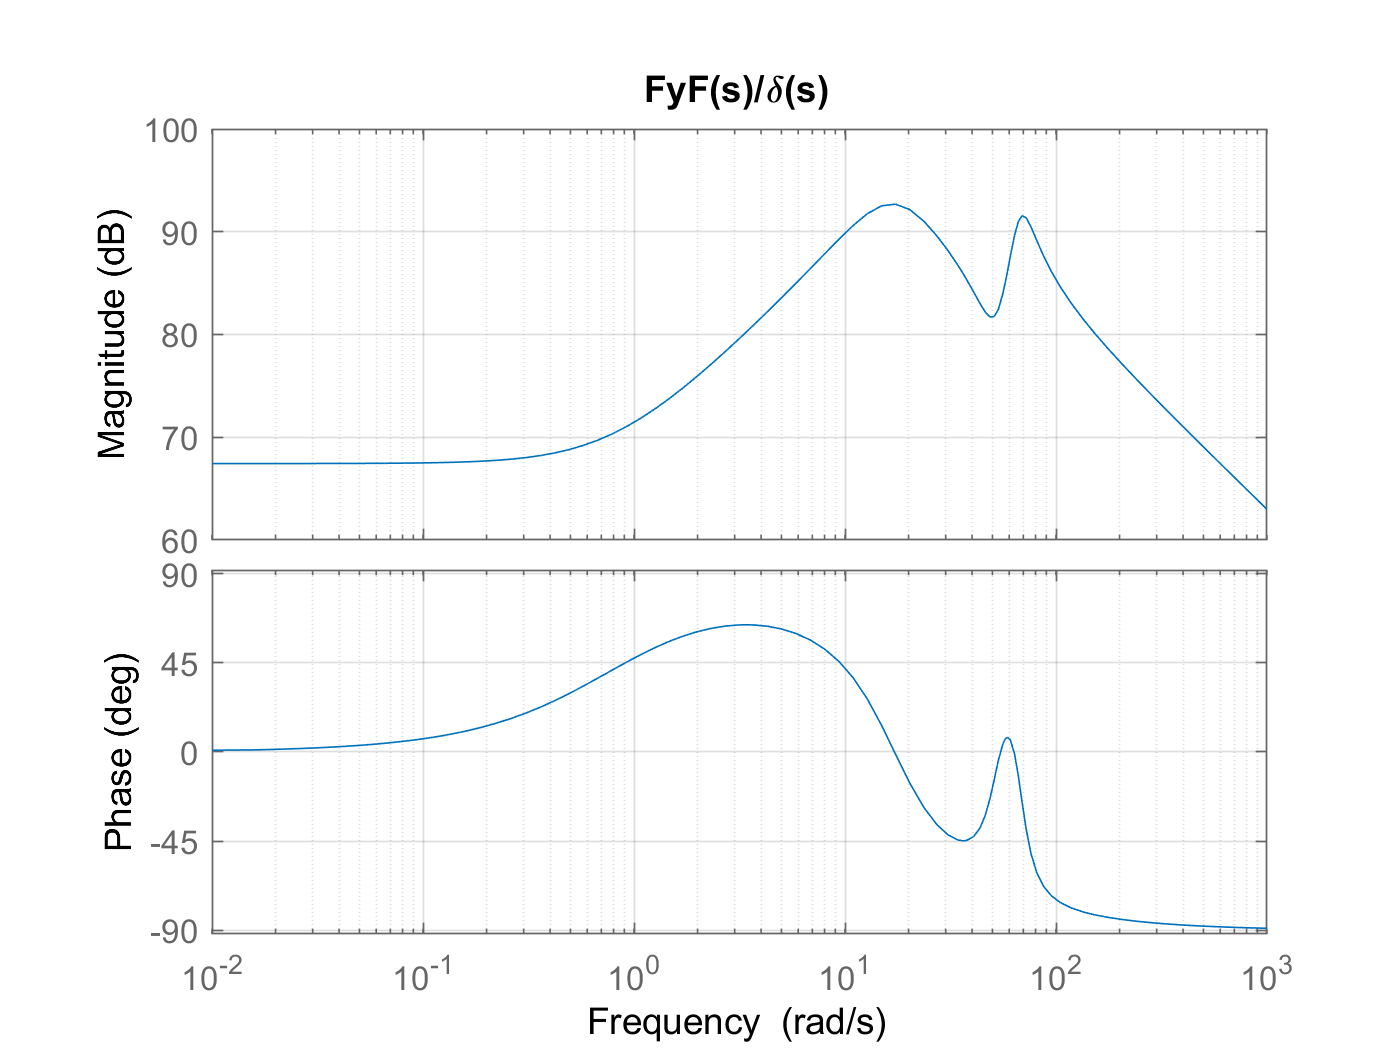

% Plot Omega(s)/delta(s) Transfer function

figure
bode(SingleTrackSS(3,1))
grid
title('FyF(s)/\delta(s)')

fprintf(' The analytical transfer function FyF(s)/delta(s) is: \n');

 The analytical transfer function FyF(s)/delta(s) is: 


G_FyF = tf(SingleTrackSS(3,1))

G_FyF =
 
  1.407e06 s^3 + 2.64e07 s^2 + 3.901e09 s + 3.153e09
  --------------------------------------------------
  s^4 + 37.52 s^3 + 5206 s^2 + 9.185e04 s + 1.339e06
 
Continuous-time transfer function.



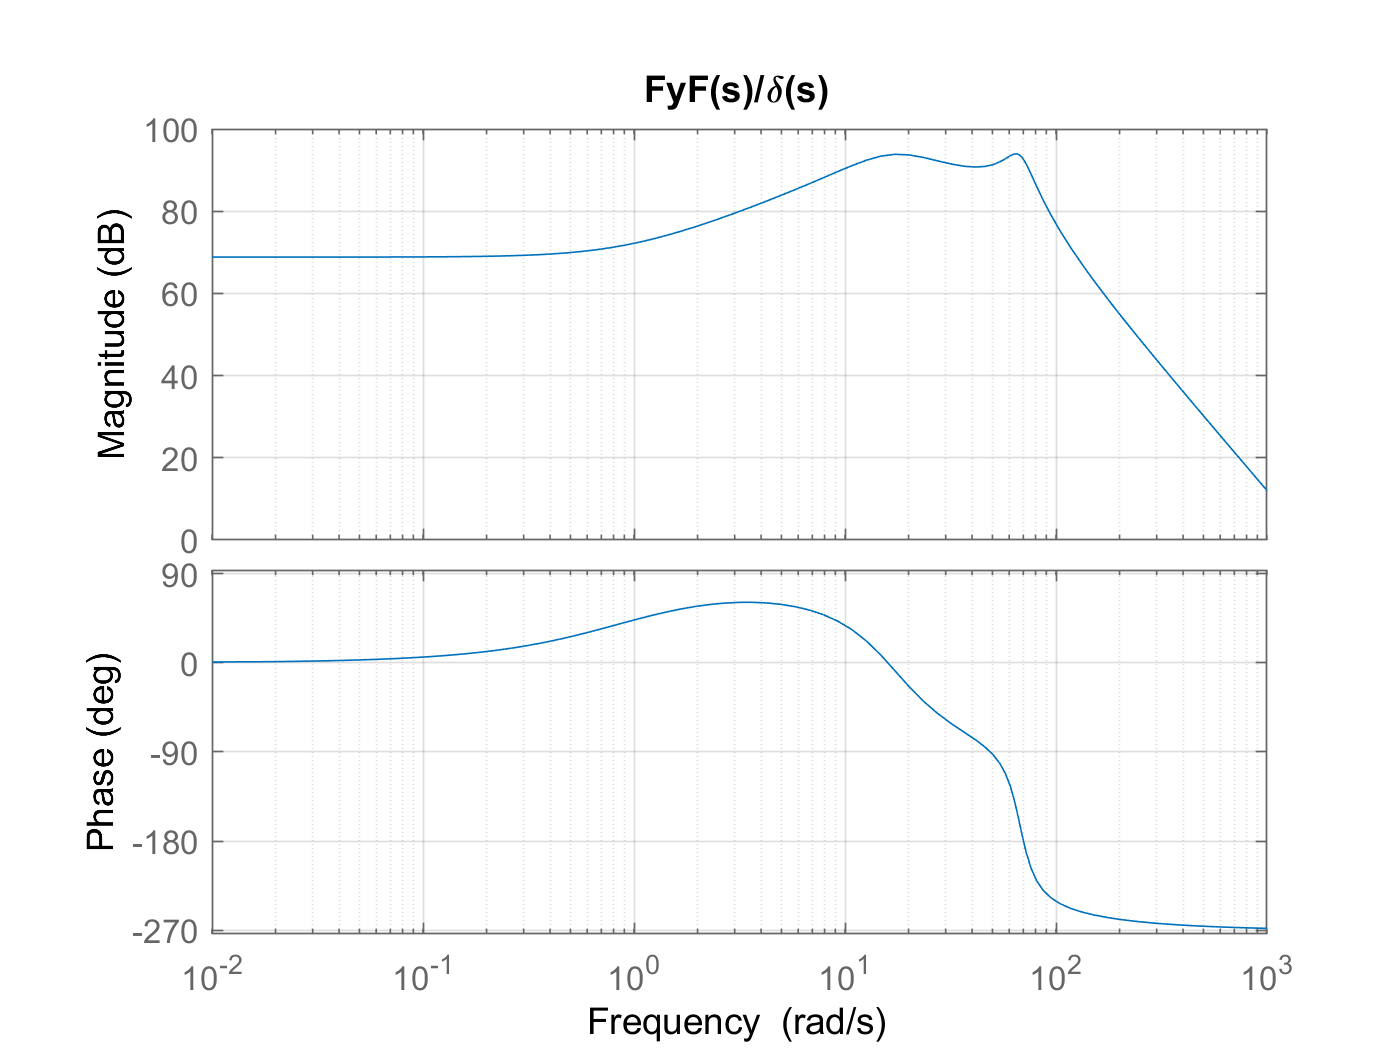

figure
bode(SingleTrackSS(4,1))
grid
title('FyF(s)/\delta(s)')

fprintf(' The analytical transfer function Fy_r(s)/delta(s) is: \n');

 The analytical transfer function Fy_r(s)/delta(s) is: 


G_FyR = tf(SingleTrackSS(4,1))

G_FyR =
 
                3.981e09 s + 3.701e09
  --------------------------------------------------
  s^4 + 37.52 s^3 + 5206 s^2 + 9.185e04 s + 1.339e06
 
Continuous-time transfer function.



## Filtering 

The body side-slip angle needs to be filtered.

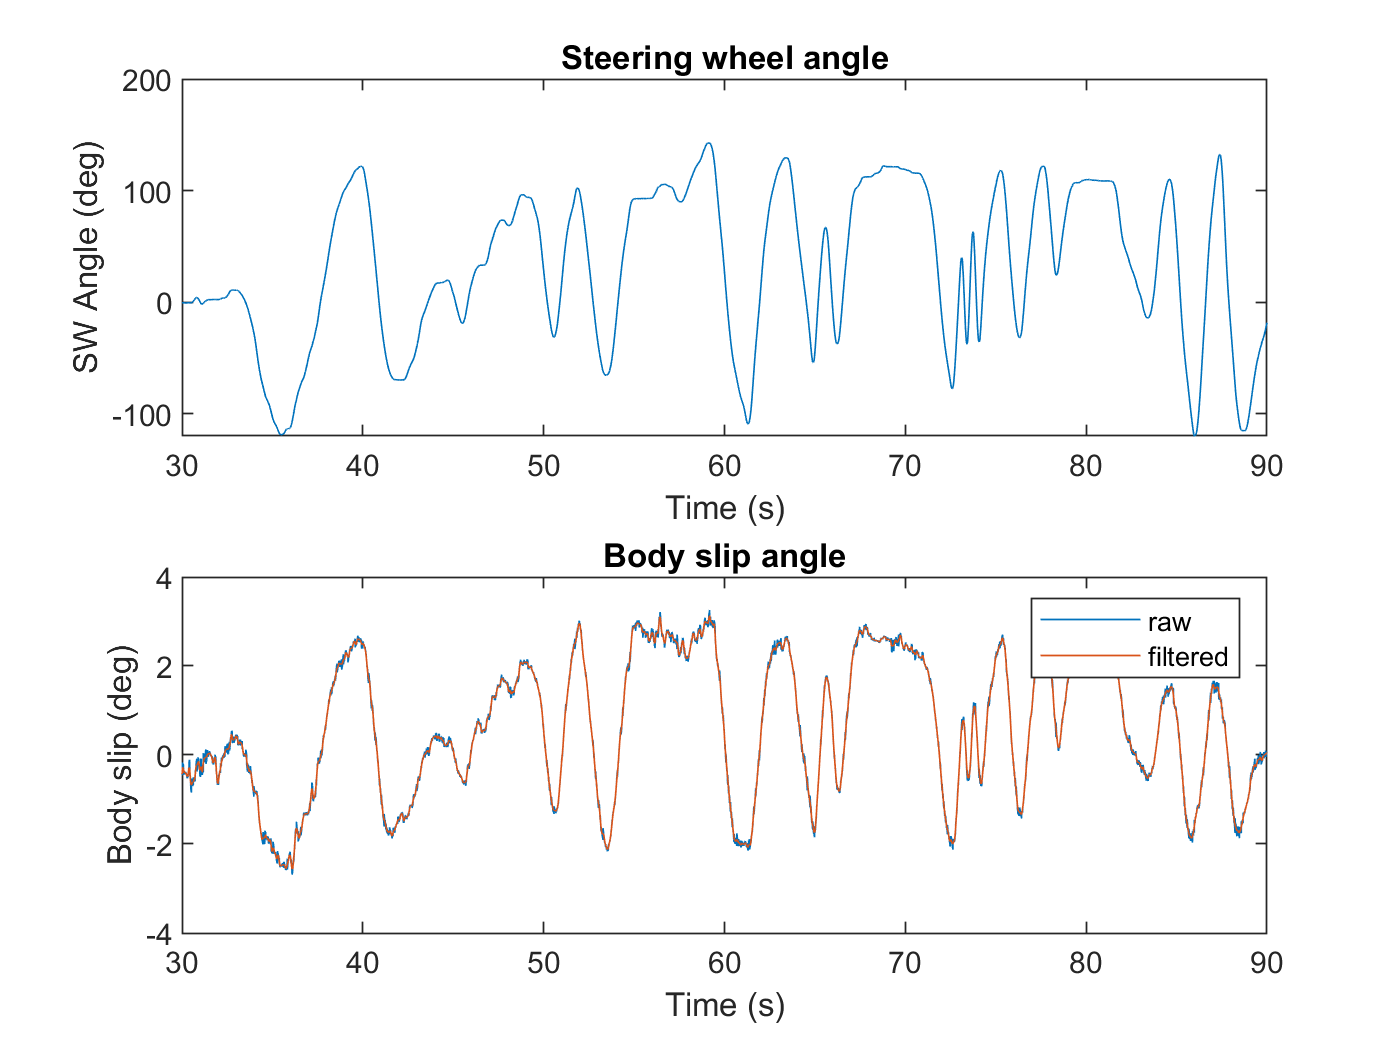

telem.body_slip_filt = smooth(telem.body_slip,50);

figure
subplot(2,1,1)
plot(telem.time, rad2deg(telem.delta_HW))
xlabel('Time (s)'); ylabel('SW Angle (deg)');
title('Steering wheel angle')

subplot(2,1,2)
plot(telem.time, rad2deg(telem.body_slip),'DisplayName','raw')
hold on
plot(telem.time, rad2deg(telem.body_slip_filt),'DisplayName','filtered')
xlabel('Time (s)'); ylabel('Body slip (deg)');
legend
title('Body slip angle')

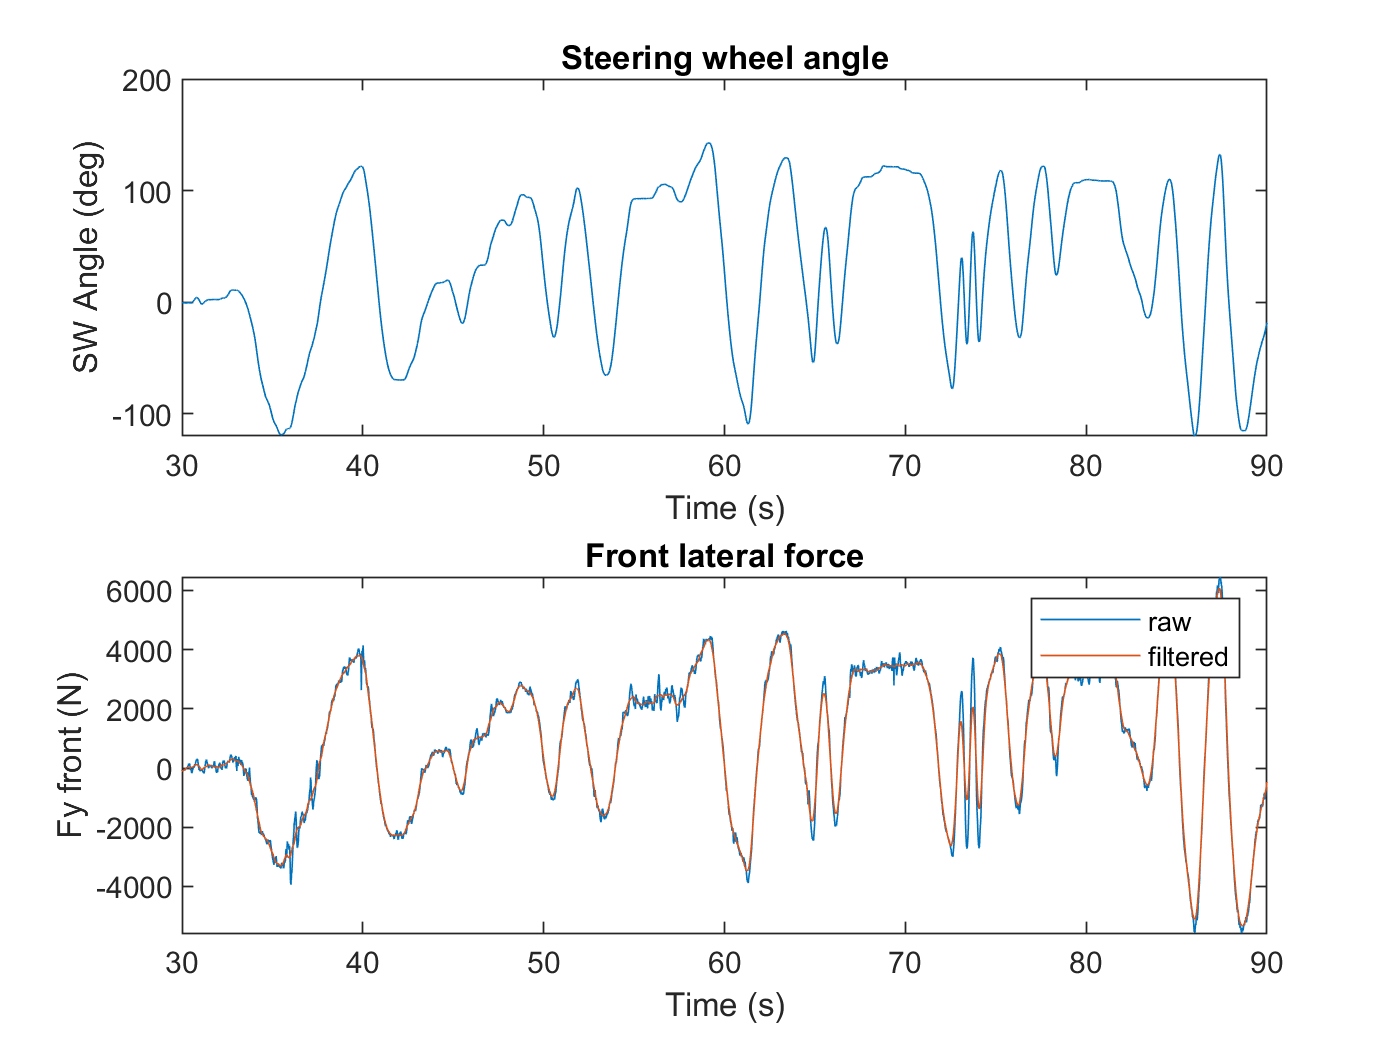

Fy_F = telem.Fy_FL+telem.Fy_FR;
Fy_F_filt = smooth(Fy_F,200);

figure
subplot(2,1,1)
plot(telem.time, rad2deg(telem.delta_HW))
xlabel('Time (s)'); ylabel('SW Angle (deg)');
title('Steering wheel angle')

subplot(2,1,2)
plot(telem.time, Fy_F,'DisplayName','raw')
hold on
plot(telem.time, Fy_F_filt,'DisplayName','filtered')
xlabel('Time (s)'); ylabel('Fy front (N)');
legend
title('Front lateral force')

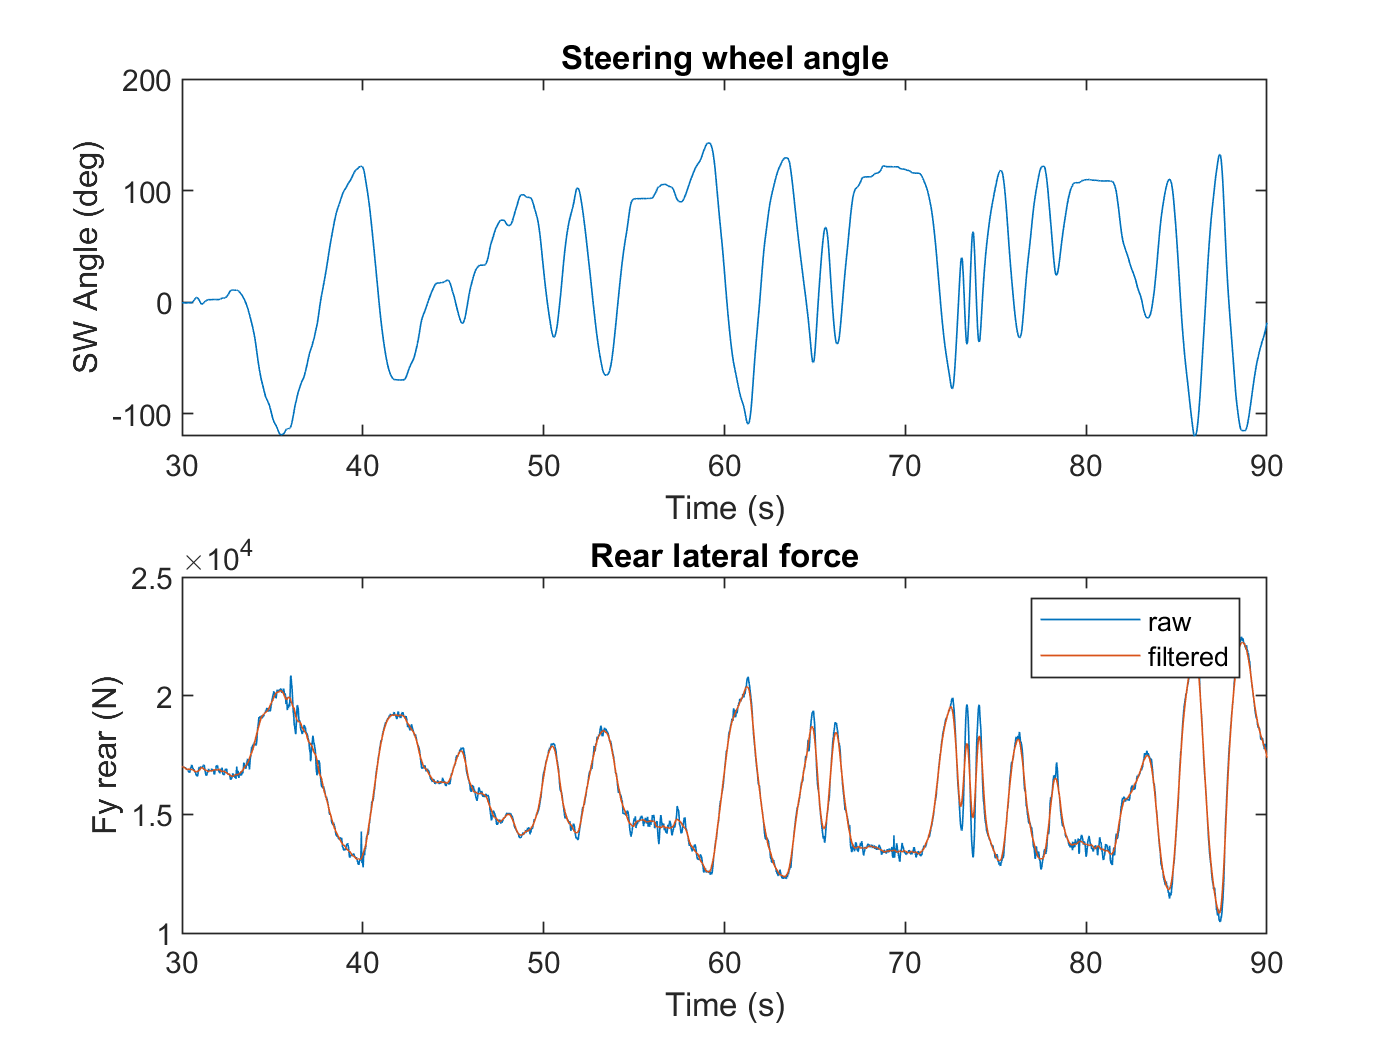

Fy_R = vehicle.mass*9.81-telem.Fy_FL-telem.Fy_FR;
Fy_R_filt = smooth(Fy_R,200);

figure
subplot(2,1,1)
plot(telem.time, rad2deg(telem.delta_HW))
xlabel('Time (s)'); ylabel('SW Angle (deg)');
title('Steering wheel angle')

subplot(2,1,2)
plot(telem.time, Fy_R,'DisplayName','raw')
hold on
plot(telem.time, Fy_R_filt,'DisplayName','filtered')
xlabel('Time (s)'); ylabel('Fy rear (N)');
legend
title('Rear lateral force')

## Estimated transfer functions 

The transfer functions are estimated from the telemetry signals using the MATLAB command `tfest`, imposing that the estimated TFs have 2 zeros and 1 pole as the analytical ones. The signals used for the estimation and their sampling time must be stored in a data object using the command `iddata`, which will be the input of `tfest`. Since we must use the equivalent steering angle at the front axle, we must divide the hand-wheel steering angle by the steering ratio. Finally, we compare the estimated transfer functions with the analytical ones.

% Signals sample time
Ts = telem.time(2) - telem.time(1);

% Estimate G_beta(s)
data_1 = iddata(telem.body_slip(idx_start:idx_end),telem.delta_HW(idx_start:idx_end)/10,Ts);

G_beta_est = tfest(data_1,2,1)

G_beta_est =
 
  From input "u1" to output "y1":
     2.202 s + 3.583
  ---------------------
  s^2 + 8.776 s + 18.24
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 1
   Number of free coefficients: 4
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using TFEST on time domain data "data_1".
Fit to estimation data: 86.68%                     
FPE: 1.288e-05, MSE: 1.287e-05                     


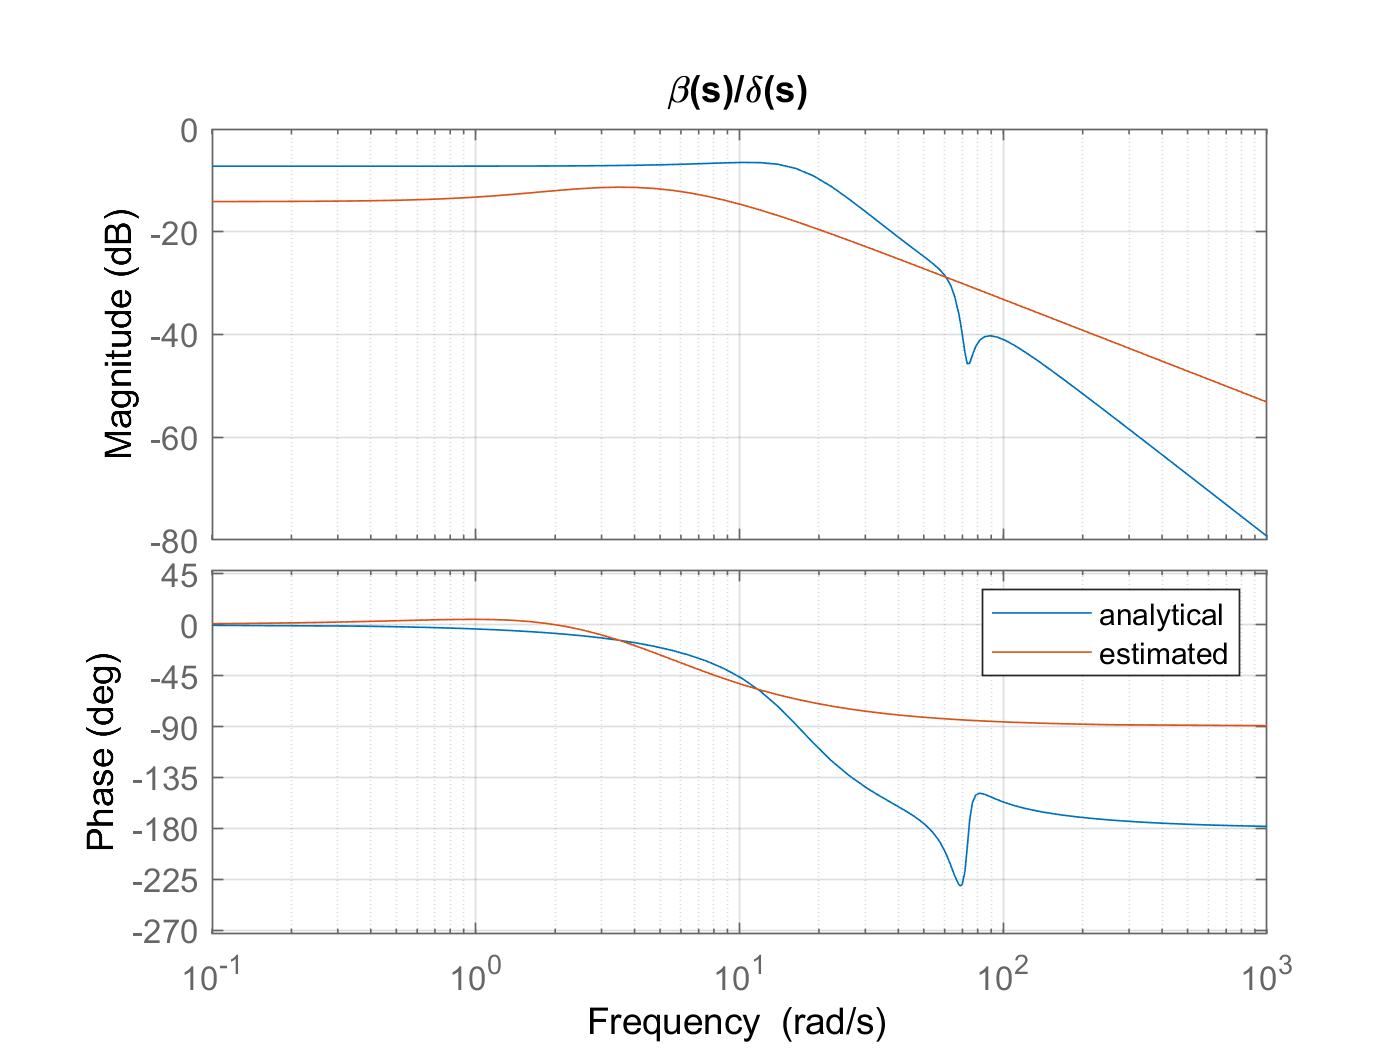


figure
hold on
bode(SingleTrackSS(1,1))
bode(G_beta_est)
grid
legend('analytical', 'estimated')
title('\beta(s)/\delta(s)')




% Estimate G_Omega(s)
data_2 = iddata(telem.yaw_rate(idx_start:idx_end),telem.delta_HW(idx_start:idx_end)/10,Ts);

G_Omega_est = tfest(data_2,2,1)

G_Omega_est =
 
  From input "u1" to output "y1":
     56.17 s + 14.71
  ---------------------
  s^2 + 20.73 s + 5.466
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 1
   Number of free coefficients: 4
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using TFEST on time domain data "data_2".
Fit to estimation data: 95.11%                     
FPE: 0.0002319, MSE: 0.0002317                     


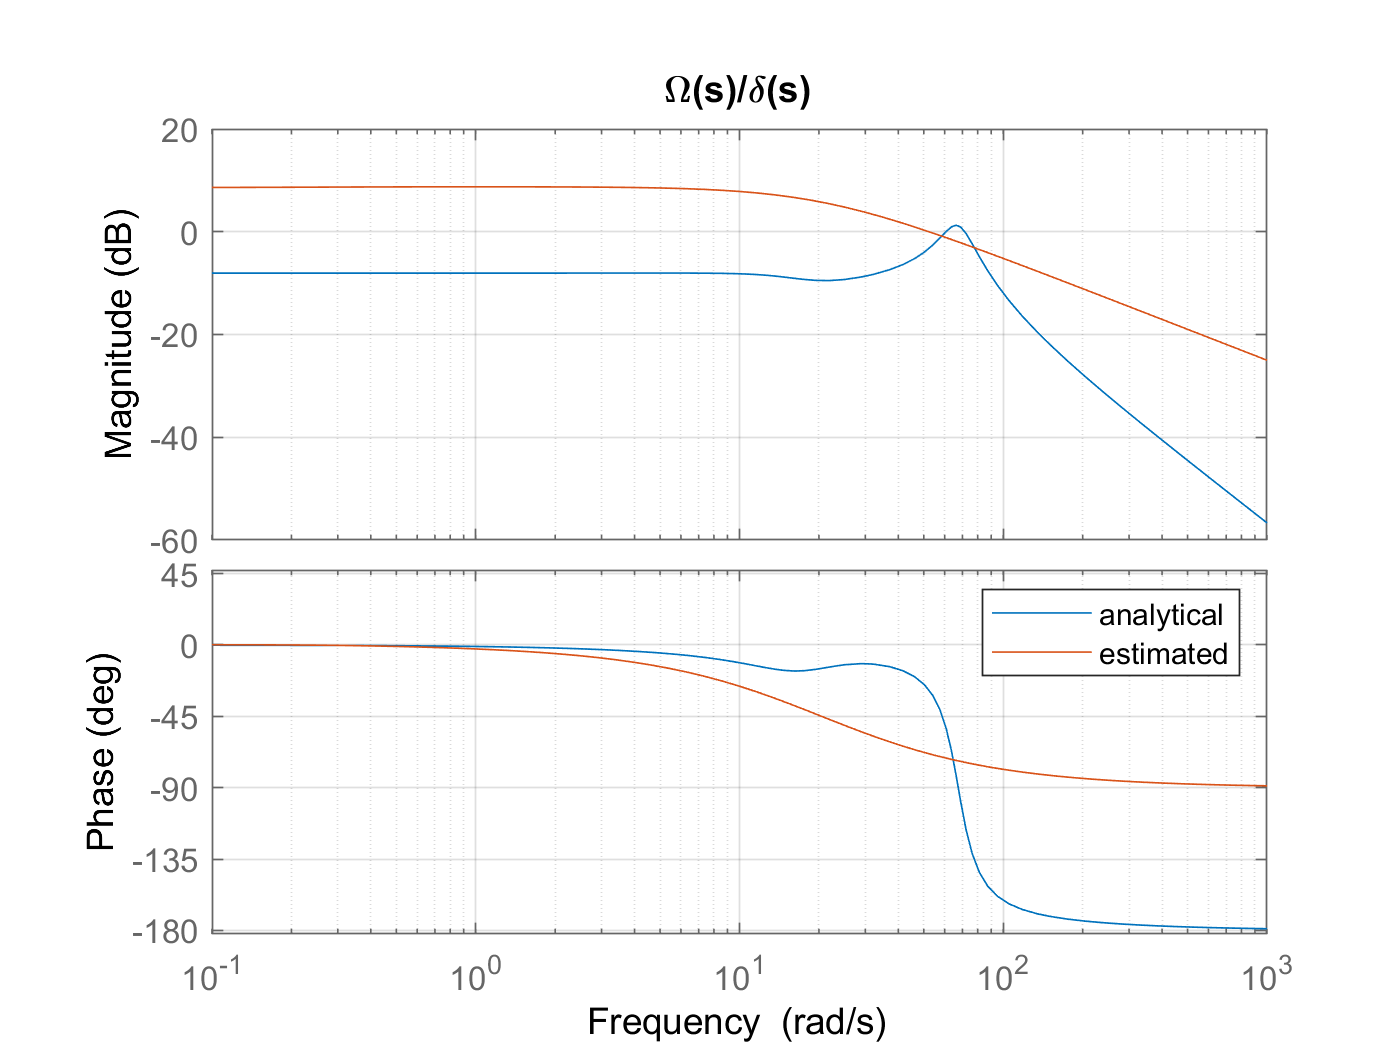



figure
hold on
bode(SingleTrackSS(2,1))
bode(G_Omega_est)
grid
legend('analytical', 'estimated')
title('\Omega(s)/\delta(s)')

% Estimate G_FyF(s)
data_3 = iddata(Fy_F_filt(idx_start:idx_end),telem.delta_HW(idx_start:idx_end)/10,Ts);

G_FyF_est = tfest(data_3,2,1)

G_FyF_est =
 
  From input "u1" to output "y1":
  4.036e06 s + 1.179e07
  ---------------------
  s^2 + 150.2 s + 685.2
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 1
   Number of free coefficients: 4
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using TFEST on time domain data "data_3".
Fit to estimation data: 89.76%                     
FPE: 4.805e+04, MSE: 4.799e+04                     


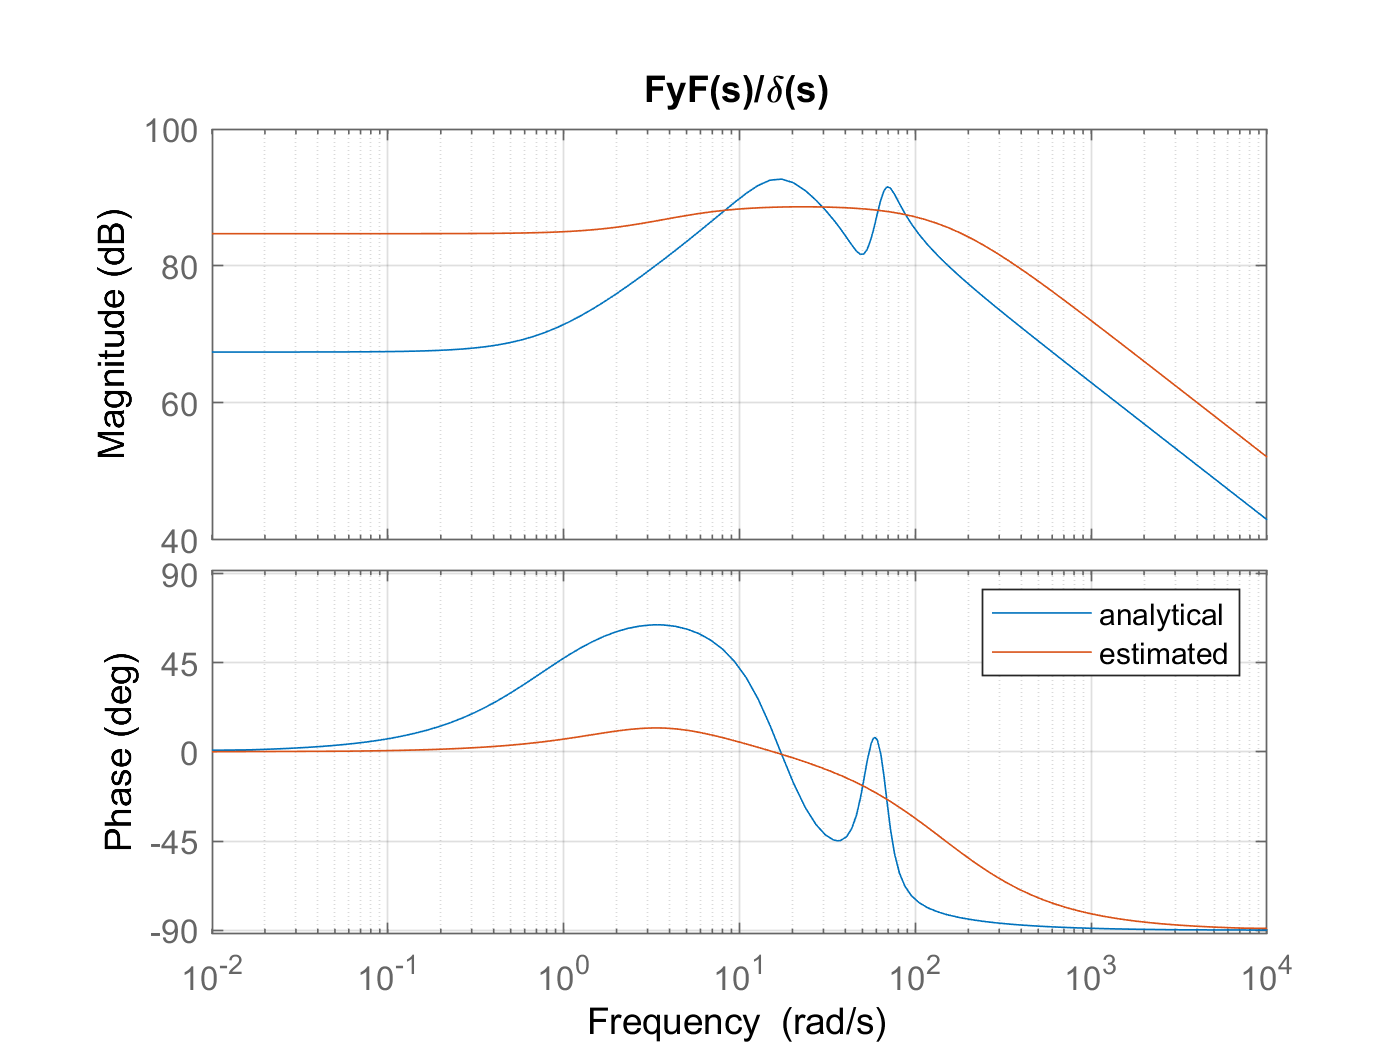

figure
hold on
bode(SingleTrackSS(3,1))
bode(G_FyF_est)
grid
legend('analytical', 'estimated')
title('FyF(s)/\delta(s)')

% Estimate G_FyR(s)
data_4 = iddata(Fy_R_filt(idx_start:idx_end),telem.delta_HW(idx_start:idx_end)/10,Ts);

G_FyR_est = tfest(data_4,2,1)

G_FyR_est =
 
  From input "u1" to output "y1":
         3537 s + 5357
  ---------------------------
  s^2 + 1.001e-05 s + 0.03863
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 1
   Number of free coefficients: 4
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using TFEST on time domain data "data_4".
Fit to estimation data: 11.29%                     
FPE: 3.606e+06, MSE: 3.602e+06                     


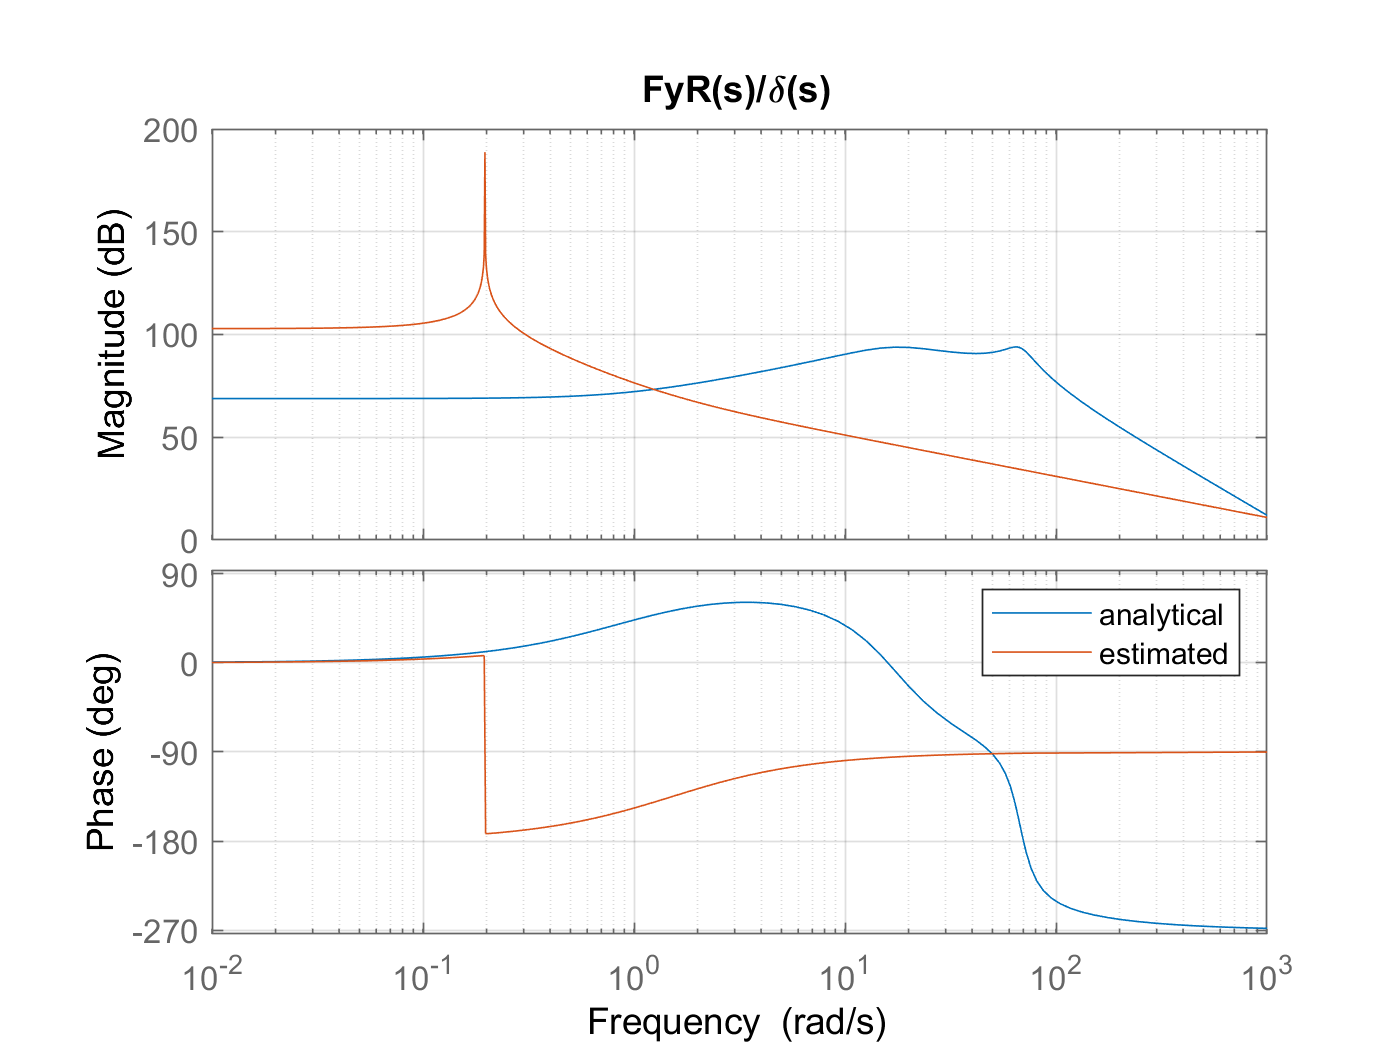


figure
hold on
bode(SingleTrackSS(4,1))
bode(G_FyR_est)
grid
legend('analytical', 'estimated')
title('FyR(s)/\delta(s)')